# pinchPlot

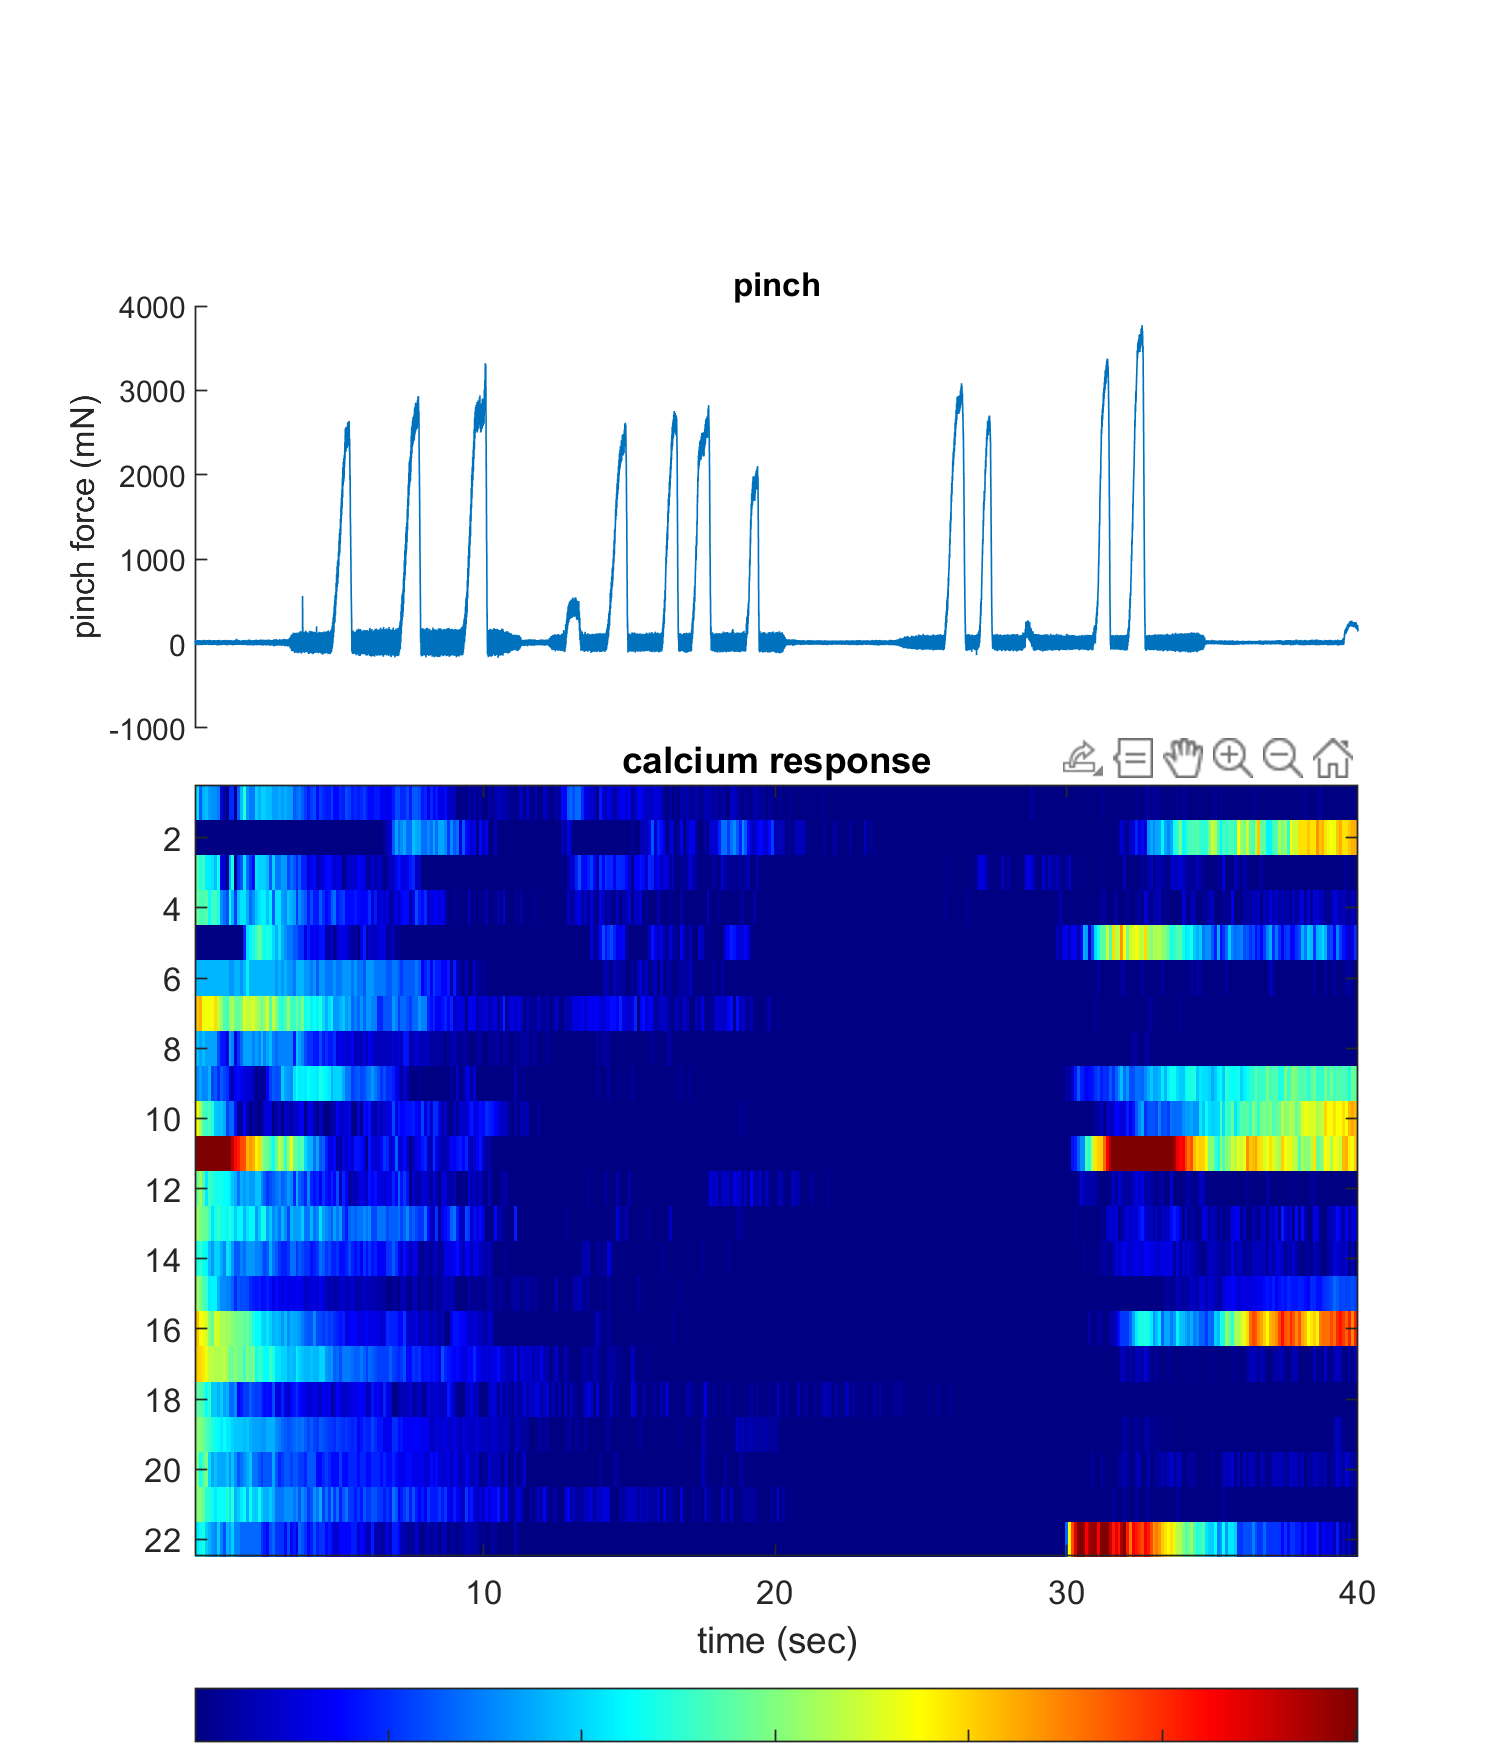

[filenameMat,pathMat] = uigetfile('Z:\GintyLab\Qi\stimulation\pinch\*.mat');
load([pathMat,filenameMat])
pinchForce = (data-0.4858) * 1300; % in mN,

% not super accurate because of the nonlinearity of the sensor,
% calibrated on  02/11/2020

fh = figure;
set(gcf,'Visible','on')
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 0.3, 0.6]);
set(gcf, 'Position',  [400, 100, 600, 700])

sfh1 = subplot(211);
line(time,pinchForce);

ylabel('pinch force (mN)'),
% ylabel('pinch intensity')
xlabel('time (s)');
set(gca,'xcolor',[1 1 1])
sfh1.Position = sfh1.Position - [0 0 0 0.10];
title("pinch")

sfh2 = subplot(212);
% imagesc(normDeltaF(:,find(sum(digitROI)))'),
imagesc(normDeltaF')
colormap(jet),
colorbar('southoutside'); set(gcf,'color','w');
% play with the colorbar scale
Max = sort(max(normDeltaF)); MaxLimit = mean(Max(end-4:end));
if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end

xticks(100:100:length(time)/Fs*fps)
timelabel = strsplit(num2str([100:100:length(time)/Fs*fps]/fps));
xticklabels(timelabel);
xlabel('time (sec)')
caxis([0 Limit])
xlim([1,length(time)/Fs*fps])
sfh2.Position = sfh2.Position + [0 0 0 0.10];
title("calcium response")